# Interface Métodos Numéricos para ED/PVI

## 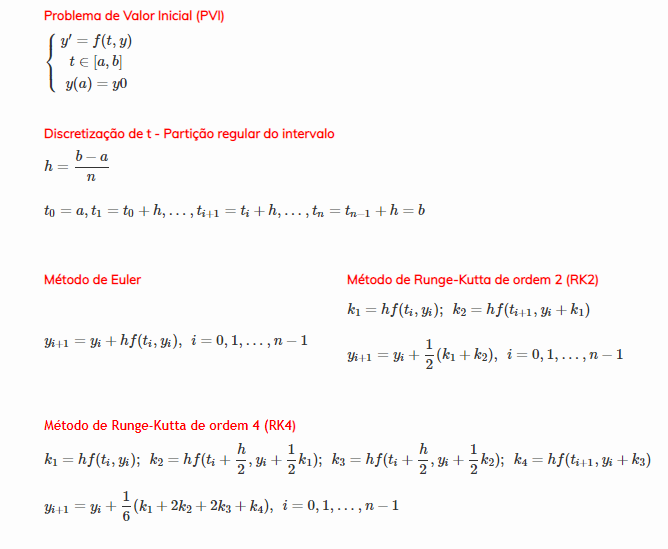

26/03/2021     Arménio Correia     armenioc@isec.pt

### **Adaptado por:**

Nuno Domingues  a2020109910@isec.pt

Miguel Neves        a2020146521@isec.pt

Daniel Albino         a2020134077@isec.pt

Data: 10/04/2021    

Método de Adams - Bashforth de ordem 4 (Passo múltiplo):

clear 
syms y(t) % Declaração de variáveis simbólicas


%Validação dos campos de entrada
while 1         
    strF = "-2*t*y";
    f =@(t,y) eval(vectorize(strF));
    try
        fTeste = f(t,y);
        break
    catch ME
        waitfor(errordlg("Introduza uma função em t e y","Erro")) 
    end
end

while 1     
    a = -1.5;
    if (~isempty(a) && isscalar(a) && isreal(a)) 
    break
    end
end

while 1
    b = 1.5;
    if (~isempty(b) && isscalar(b) && isreal(b) && b>a) 
    break
    end
end


    n = 21;

while 1
    y0 = 2;
    if (~isempty(y0) && isscalar(y0) && isreal(y0)) 
    break
    end
end
       
% Atribuição de vetores para guardar os valores retornados pelas funções
yEuler = NEuler(f,a,b,n,y0);
yEulerM = NEulerM(f,a,b,n,y0);
yRK2 = NRK2(f,a,b,n,y0);
yRK4 = NRK4(f,a,b,n,y0);
yODE45 = NODE45(f,a,b,n,y0);
yNAdams = NAdams(f,a,b,n,y0);

% Solução exata
sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);

% Cálculo de erros dos métodos numéricos em relação à solução exata
erroEuler = abs(yExata-yEuler);
erroEulerM = abs(yExata-yEulerM);
erroRK2 = abs(yExata-yRK2);
erroRK4 = abs(yExata-yRK4);
erroODE45 = abs(yExata-yODE45);
erroAdams = abs(yExata-yNAdams);

% Gráfico da solução exata
plot(t,yExata,"-ro")

EscolhaMetodo = "Euler/RK2";

switch EscolhaMetodo           
    case "Euler"
        tabela = [t.',yExata.',yEuler.',erroEuler.'];
        %array2table(tabela,"VariableNames",{'t','Exata','Euler','erroEuler'})
        nome_var = {'t','Exata','Euler','erroEuler'};
        hold on
        plot(t,yEuler,"-g*")
        legend('Exata','Euler')
    
    case "EulerM"
        tabela = [t.',yExata.',yEulerM.',erroEuler.'];
        %array2table(tabela,"VariableNames",{'t','Exata','EulerM','erroEulerM'})
        nome_var = {'t','Exata','EulerM','erroEulerM'};
        hold on
        plot(t,yEuler,"-g*")
        legend('Exata','EulerM')
    
    case "RK2"
        tabela = [t.',yExata.',yRK2.',erroRK2.'];
        %array2table(tabela,"VariableNames",{'t','Exata','RK2','erroRK2'})
        nome_var = {'t','Exata','RK2','erroRK2'};
        hold on
        plot(t,yRK2,"-g*")
        legend('Exata','RK2')
        
    case "Euler/RK2"    %Acrescentado para resolver o exercício 3.(C)
        tabela = [t.',yExata.',yEuler.',yRK2.',erroEuler.',erroRK2.'];
        %array2table(tabela,"VariableNames",{'t','Exata','RK2','erroRK2'})
        nome_var = {'t','Exata','Euler','RK2','erroEuler','erroRK2'};
        hold on
        plot(t,yEuler,"-g*")
        plot(t,yRK2,"-mo")
        legend('Exata','Euler','RK2')
        
    case "RK4"
        tabela = [t.',yExata.',yRK4.',erroRK4.'];
        %array2table(tabela,"VariableNames",{'t','Exata','RK4','erroRK4'})
        nome_var = {'t','Exata','RK4','erroRK4'};
        hold on
        plot(t,yEuler,"-g*")
        legend('Exata','RK4')
    case "ODE_45"
        tabela = [t.',yExata.',yODE45.',erroODE45.'];
        %array2table(tabela,"VariableNames",{'t','Exata','ODE45','erroODE45'})
        nome_var = {'t','Exata','ODE45','erroODE45'};
        hold on
        plot(t,yODE45,"-b*")  
        legend('Exata','ODE45')
    case "NA"
        tabela = [t.',yExata.',yNAdams.',erroAdams.'];
        %array2table(tabela,"VariableNames",{'t','Exata','Adams','erroAdams'})
        nome_var = {'t','Exata','Adams','erroAdams'};
        hold on
        plot(t,yNAdams,"-b*")  
        legend('Exata','Adams')
    case "TodosMetodos"                 
        tabela = [t.',yExata.',yEuler.',yEulerM.',yRK2.',yRK4.',yODE45.',yNAdams.',erroEuler.',erroEulerM.',erroRK2.',erroRK4.',erroODE45.',erroAdams.'];
        %array2table(tabela,"VariableNames",{'t','Exata','Euler','EulerMelhorado','RK2','RK4','ODE45','Adams','erroEuler','erroEulerM','erroRK2','erroRK4','erroODE45','erroAdams'})
        nome_var = {'t','Exata','Euler','EulerMelhorado','RK2','RK4','ODE45','Adams','erroEuler','erroEulerM','erroRK2','erroRK4','erroODE45','erroAdams'};
        hold on
        plot(t,yEuler,"-b*") 
        plot(t,yEulerM,"-mx") 
        plot(t,yRK2,"-y*")  
        plot(t,yRK4,"-c*")  
        plot(t,yODE45,"-gx")  
        plot(t,yNAdams,"--kx") 
        legend('Exata','Euler','EulerMelhorado','RK2','RK4','ODE45','Adams')
end
array2table(tabela,"VariableNames",nome_var) 

ans = 22×6 table
        t        Exata     Euler      RK2      erroEuler    erroRK2 
    _________    ______    ______    ______    _________    ________

         -1.5         2         2         2           0            0
      -1.3571    3.0081    2.8571    2.9825     0.15096     0.025598
      -1.2143    4.3434     3.965    4.2787     0.37839     0.064663
      -1.0714    6.0206    5.3406    5.9031     0.67997      0.11752
     -0.92857    8.0117    6.9755    7.8294      1.0362       0.1823
     -0.78571    10.235    8.8262      9.98      1.4087      0.25491
     -0.64286    12.552    10.808    12.222      1.7445      0.32959
         -0.5    14.778    12.793    14.378      1.9855      0.39983
     -0.35714    16.703     14.62    16.244       2.083      0.45944
     -0.21429    18

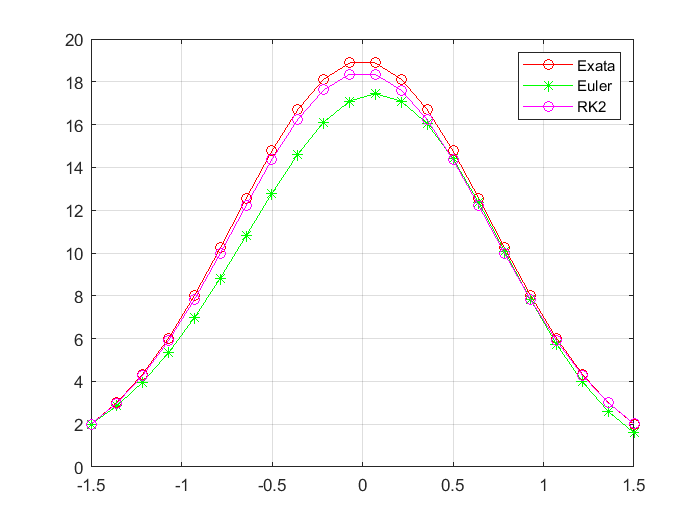

grid on
hold off